## Lab 3 Step 1 Starter Code

clear all;
close all;
clc;
% load csv data. Put data into column vectors.
% convert from degrees to radians
M = readmatrix("mocap_data.csv");

% Number of rows in M = Number of samples from motion capture system
N = size(M,1);

t = M(:,1);
x = M(:,2);
y = M(:,3);
z = M(:,4);

p = [x y z]; % position vector (in m)

roll = deg2rad(M(:,5));
pitch = deg2rad(M(:,6));
yaw = deg2rad(M(:,7));

**Problem 1a**

For this problem, you need to use `subplot.`

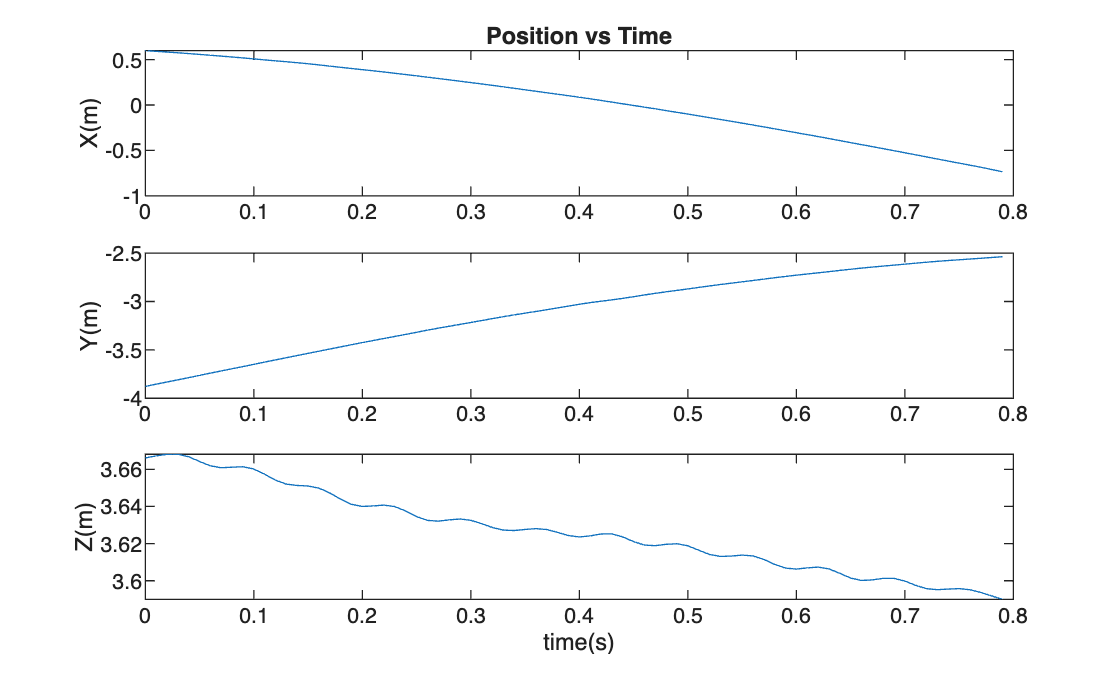

% plot x,y,z data in subplots

figure(1);
subplot(3,1,1);
plot(t, x);
ylabel('X(m)')
title('Position vs Time')

subplot(3,1,2); 
plot(t,y);
ylabel('Y(m)')

subplot(3,1,3);
plot(t, z);
ylabel('Z(m)')
xlabel('time(s)');

**Problem 1b**

We approximate the velocities using the definition of a derivative, and replacing $h$ with $\Delta t$.


$$v(t) = \lim_{h \rightarrow 0^+} \frac{p(t+h)-p(t)}{h} \Rightarrow
v(t_i) \approx  \frac{p(t_{i+1})-p(t_i)}{t_{i+1}-t_i} $$


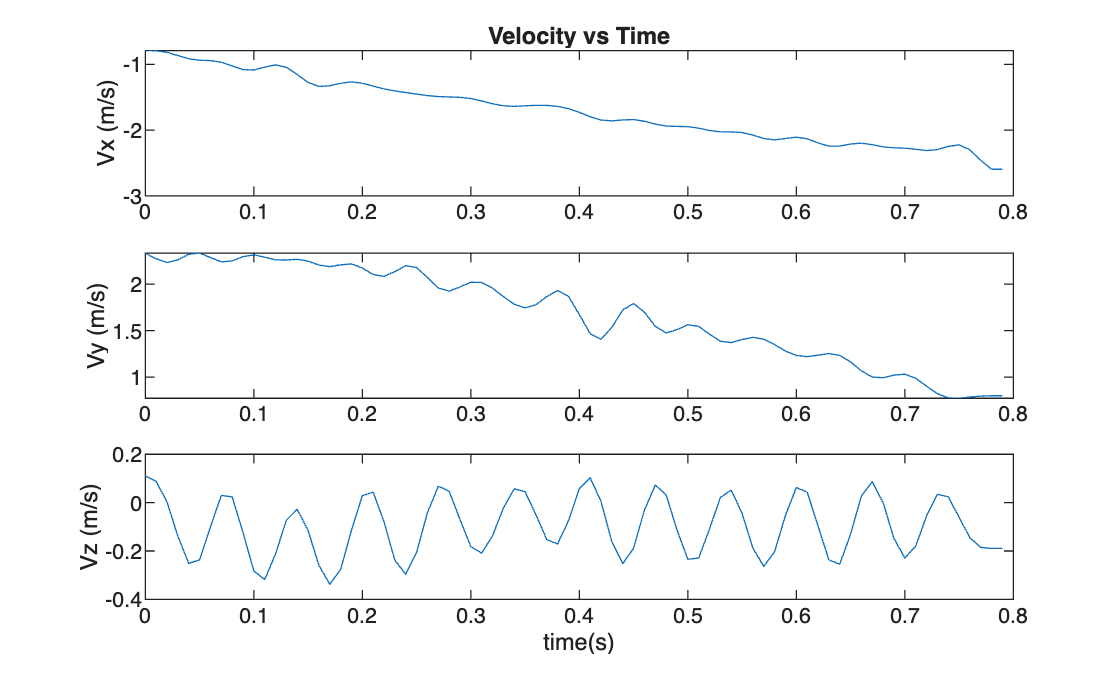

% Calculate velocities numerically
v = zeros(N,3);
for i=1:N-1
    
    v(i,:) = (p(i + 1, :) - p(i, :))/(t(i + 1) - t(i));
    % v(i,:) = ...
end
v(end,:) = v(end-1,:);

figure (2);

subplot(3,1,1);
plot(t, v(:,1));
ylabel('Vx (m/s)')
title('Velocity vs Time')

subplot(3,1,2); 
plot(t, v(:,2));
ylabel('Vy (m/s)')

subplot(3,1,3);
plot(t, v(:,3));
ylabel('Vz (m/s)')
xlabel('time(s)');



% plot the figure

**Problem 1c**

First we need to convert roll-pitch-yaw to rotation matrices. You can either use change of basis (MLS p. 31-33) or use the `eul2rotm` function from the Robotics Toolbox to do the job. (This part is done for you.)

% convert rpy to rotation matrices by hand (MLS p. 31-33)
R = zeros(3,3,N);



% using inline functions to make our code easier to read
Rx = @(phi) [1 0 0; 0 cos(phi) -sin(phi); 0 sin(phi) cos(phi)];
Ry = @(beta) [cos(beta) 0 sin(beta); 0 1 0; -sin(beta) 0 cos(beta)];
Rz = @(alpha) [cos(alpha) -sin(alpha) 0; sin(alpha) cos(alpha) 0; 0 0 1];

for i=1:N
    R(:,:,i) = Rz(yaw(i))*Ry(pitch(i))*Rx(roll(i));
end

% convert rpy to rotation matrices using Robotics Toolbox
% this code works identically to above!
% eul = [yaw pitch roll];
% Rotm = eul2rotm(eul,'ZYX');



Now implement ECE569_MatrixLog3, ECE569_so3ToVec, ECE569_VecToso3, ECE569_AxisAng3 in their respective .m files. When you have written them, run the command "runtests" in the Command Window.

Once you have done that, take a matrix logarithm to obtain $$\widehat{\omega} \theta$ (the exponential coordinate of $R=e^{\widehat{\omega}\theta}$)$. Then, perform manipulations to obtain $\hat \omega$ and $\theta$ where $\omega$ is a unit vector representing the axis of rotation.

% get (w,theta) from e^(w_hat_theta)
w = zeros(N,3);
theta = zeros(N,1);
for i=1:N
    Ri = R(:,:,i);

    % Calculate the matrix logarithm as we learned in class
    % See MR textbook eqn. 3.58
    
    % you will need to assign values to w(i,:) and theta(i)

    w_hat_theta = ECE569_MatrixLog3(Ri);

    w_vec_theta = ECE569_so3ToVec(w_hat_theta);

    [w_i, theta_i] = ECE569_AxisAng3(w_vec_theta);
    
    w(i,:) = w_i';
    theta(i) = theta_i;

end

Finally, plot the desired signals with appropriate labels.

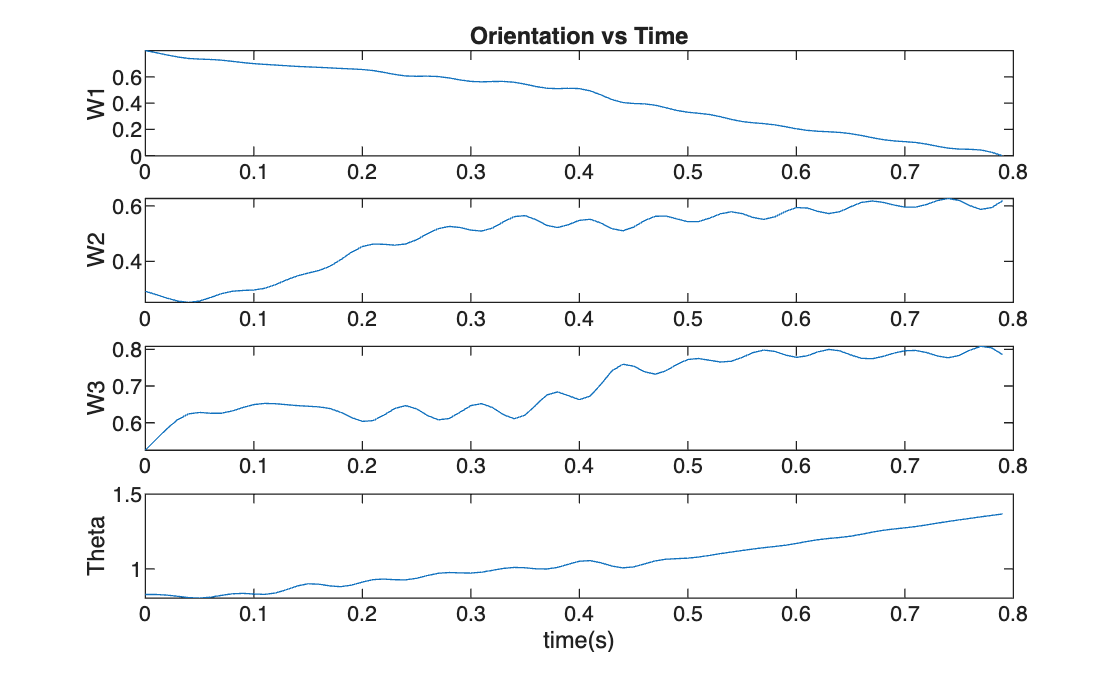

% subplots
figure (3);

    subplot(4,1,1);
    plot(t, w(:,1));
    ylabel('W1')
    title('Orientation vs Time')
    
    subplot(4,1,2); 
    plot(t, w(:,2));
    ylabel('W2')
    
    subplot(4,1,3);
    plot(t, w(:,3));
    ylabel('W3')

    subplot(4,1,4);
    plot(t, theta);
    ylabel('Theta');

    xlabel('time(s)');

**Problem 1d**

Take a matrix logarithm of $R(t_i)^\top R(t_{i+1})$ and then do manipulations to obtain $\omega^b(t_i)$, which we defined as $\omega^b(t_i)=\frac{\omega(t_i)\theta(t_i)}{t_{i+1}-t_i}$.

% Calculate angular velocity
w = zeros(N,3);
wb = zeros(N,3)

wb =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


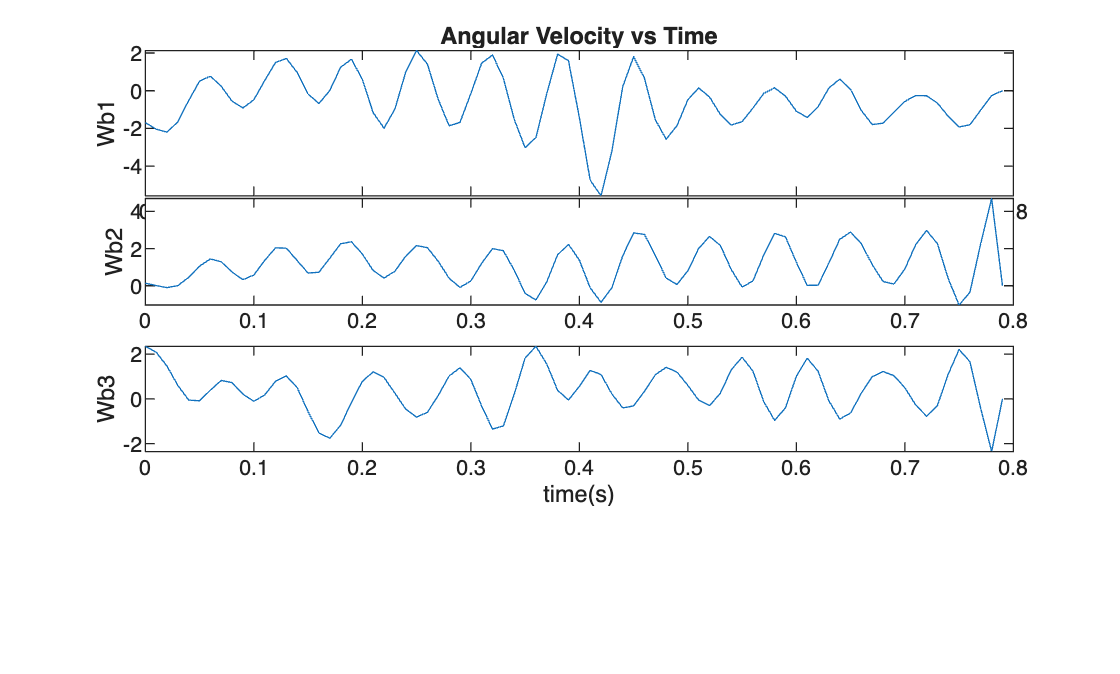

theta = zeros(N,1);
for i=1:N - 1
 
    w_hat_theta = ECE569_MatrixLog3(R(:,:,i)' *  R(:,:, i +1));

    w = ECE569_so3ToVec(w_hat_theta);
    theta(i) = norm(w);

    if(theta(i) == 0)
        w_i = zeros(3,1);
    else
        w_i = w / theta(i);
    end
    wb(i, :) = w_i * theta(i) / (t(i + 1) - t(i));

end


% make subplot

figure (4);

    subplot(3,1,1);
    plot(t, wb(:,1));
    ylabel('Wb1')
    title('Angular Velocity vs Time')
    
    subplot(4,1,2); 
    plot(t, wb(:,2));
    ylabel('Wb2')
    
    subplot(4,1,3);
    plot(t, wb(:,3));
    ylabel('Wb3')

    xlabel('time(s)');

**Problem 1e**

Plot the function $d(R(t),R_d)^2 = 2Tr(I-R^\top R_d)$ 

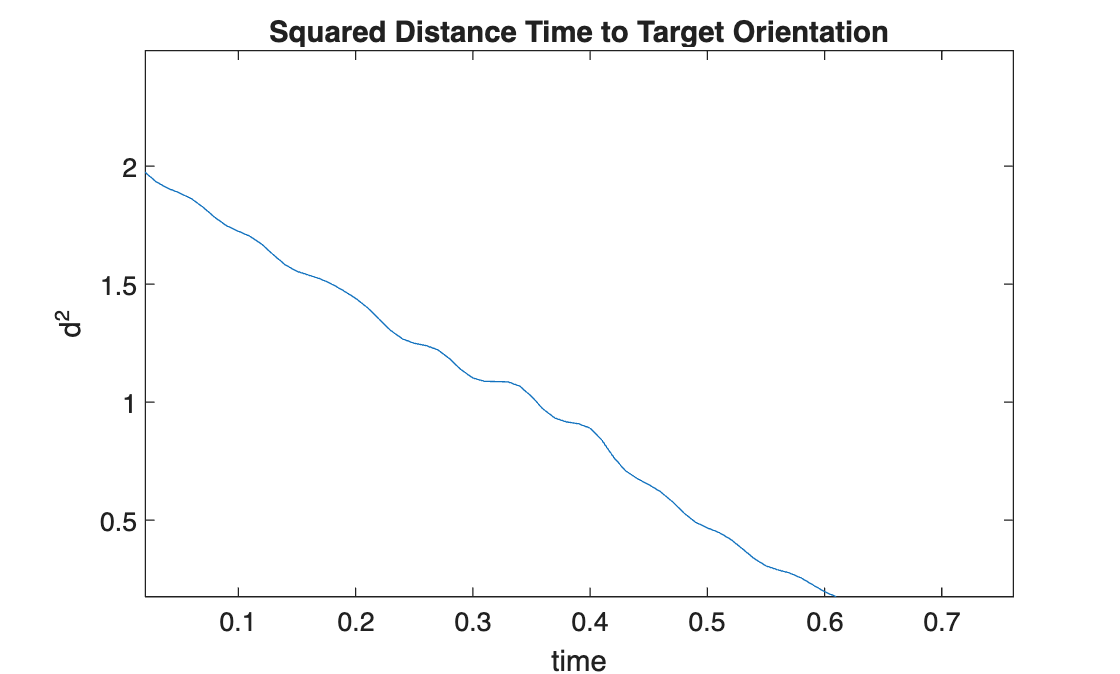

% calculate d^2
% plot the error from current rotation to desired rotation Rd = R(t_N)

theta = zeros(N,1);
d = zeros(N,1);

for i=1:N 
    
    d(i) = 2 * trace(eye(3) - R(:,:,i)' * R(:,:,end));

end


figure (5);

    plot(t, d);
    ylabel('d^2');
    xlabel('time');
    title('Squared Distance Time to Target Orientation');